# Worksheet 7

Problem 1

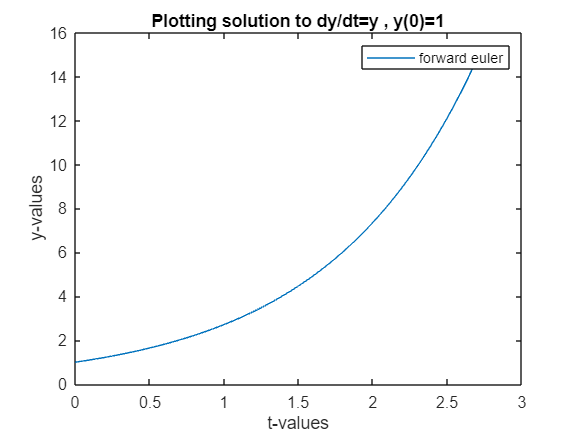


% Part 5 and 6-- solving for dy/dt = y , y(0)=1  with t over [0,e]
f = @(t,y) y; 

tspan = [0 , exp(1)];
ic = 1;

nsteps = 1000;
[t,y] = forward_euler_refactor(f,tspan,ic,nsteps);

% Plots for Part 7 -- I plot forward_euler_refactor function as the
% solution
figure()
plot(t,y);
xlabel('t-values');
ylabel('y-values');
title('Plotting solution to dy/dt=y , y(0)=1')
legend('forward euler');

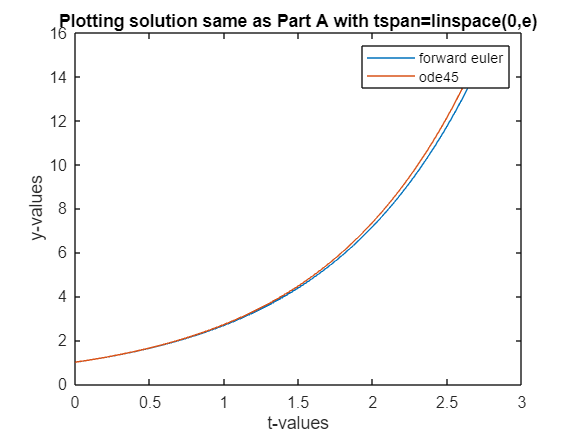


% Part 8 -- repeating Part 5-7 with tspan = linspace(0,e)
% Here, we need to make nsteps a value that will make the outputs of our
% forward_euler_refactor have the same length as the outputs from our
% ode45. To do that, we go to our workspace and do [t_ode45,y_ode45] = ode45(f,tspan,
% ic) and then do length(y_ode45) to give us the length of output for ode45,
% then we take this value and set it equal to our nsteps
tspan = linspace(0,exp(1));
ic = 1;

[t_ode45,y_ode45] = ode45(f,tspan,ic);

nsteps = (length(y_ode45)-1);
[t,y] = forward_euler_refactor(f,tspan,ic,nsteps);

figure()
plot(t,y);
hold on
plot(t_ode45,y_ode45);
xlabel('t-values');
ylabel('y-values');
title('Plotting solution same as Part A with tspan=linspace(0,e)')
legend('forward euler','ode45');

Problem 2

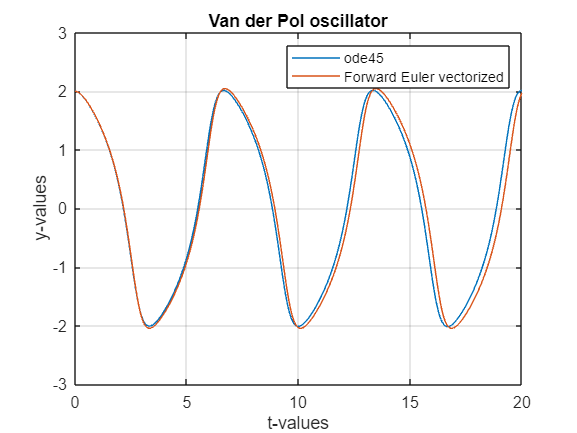

% Part 3
f_vdp = @(t,v) [v(2); v(2) - v(2).*((v(1).^2)) - v(1)];

% Solving and Plotting using ode45
y0 = [2, 0];
tspan = [0 20];
[t_ode45,v_ode45] = ode45(f_vdp,tspan, y0);



% Solving and Plotting using foward_euler_vec
tspan = [0,20];
ic = [2, 0];

nsteps = 1000;
[t,v] = forward_euler_vec(f_vdp,tspan,ic,nsteps);

figure();
plot(t_ode45,v_ode45(:,1));
hold on
plot(t,v(:,1));
grid on
ylim([-3,3]);
xlabel('t-values');
ylabel('y-values');
legend('ode45', 'Forward Euler vectorized');
title('Van der Pol oscillator')

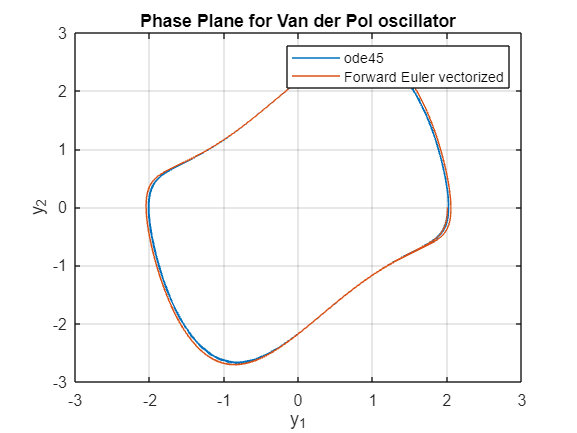


figure();
plot(v_ode45(:,1), v_ode45(:,2));
hold on
plot(v(:,1), v(:,2));
grid on
xlabel('y_1');
ylabel('y_2');
legend('ode45', 'Forward Euler vectorized');
title('Phase Plane for Van der Pol oscillator');

Problem 3

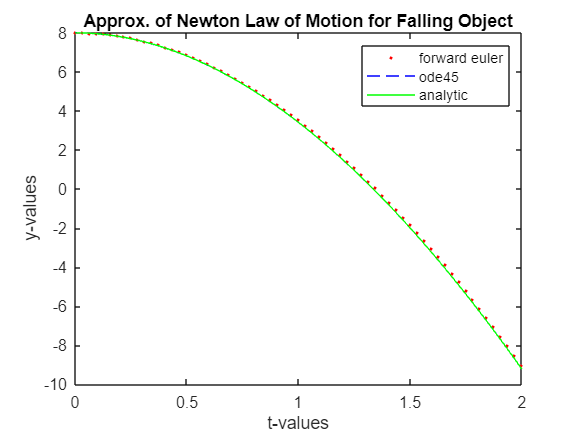

% Part 1 -- solving the problem analytically 
% Analytic solution: x(t) = -49t -245e^(-0.2t) + 253 , x(0) = 8, x'(0) = 0
% Handwritten work on uploaded PDF 

% Part 2A -- Using ODE45

f_ode45 = @(t,v) [v(2); (-9.8)-(0.2.*v(2))];
y0= [8,0];
tspan = [0,2];
[t_ode45,v_ode45] = ode45(f_ode45, tspan, y0);

% Part 2B -- Using Forward Euler Vec
tspan = [0,2];
ic = [8,0];

nsteps = (length(v_ode45)-1);
[t,v] = forward_euler_vec(f_ode45,tspan,ic,nsteps);

% Part 3 -- Using Analytic Solution
f_analytic = @(t) -49.*t -245*exp((-0.2).*t) + 253;

% Plotting all the approximation methods on the same graph
figure()
plot(t,v(:,1),'k.', 'Color','red');
hold on
plot(t_ode45,v_ode45(:,1),'LineStyle','--', 'Color','blue');
plot(t,f_analytic(t),'LineWidth',0.5, 'Color','green');
xlabel('t-values');
ylabel('y-values');
title('Approx. of Newton Law of Motion for Falling Object')
legend('forward euler','ode45','analytic')


% Part 4-- ode45 is expected to be more accurate due to its adaptive step size, which allows it to handle stiff equations and rapid changes in the solution more effectively than the Forward Euler method with a fixed step size. The accuracy loss in less accurate methods like Forward Euler typically results from the accumulation of truncation errors at each step, especially over intervals where the solution changes rapidly or the ODE is stiff.
% Calculate the average norm of the error per number of timesteps for each of the numerical solutions
error_forward_euler = norm(v(:,1) - f_analytic(t), inf) / nsteps

error_forward_euler = 0.0032

error_ode45 = norm(y_analytic - v_ode45(:,1))/length(t_ode45)

error_ode45 = 6.2536e-10

% This suggests that ODE45 is much more accurate than Forward Euler for this problem. The less accurate method (Forward Euler) loses accuracy due to the larger time step size and the resulting truncation error.


% Part 5 -- we are using an initial guess of [0, 20] for the time when the mass hits the ground.
t_ground = fzero(@(t) f_analytic(t), [0, 20])

t_ground = 1.3346

% The mass hits the ground at y = 0. That is roughly at time t = 1.33